# Sample Generator

BE CAREFUL, THIS SCRIPT CAN OVERWRITE FILES

Expert data generation for behavioural cloning

Inputs

- Environement

- Horizont length for sampled trajectories: Nhorizon

clc
clear all
close all
rng(0)
generate_data = true; % Run data generation simulation
save_buffer = false; % Save buffer of actual run of the script
Nepisodes = 100000; % Number of simulations
Nhorizon = 1 % 20e-3/1e-4  % 20ms in 100us steps = 200 steps, Number of steps per simulation

Nhorizon = 1

## M3C parameters

Simulation and control steps

%% Simulation
Ts = 1e-5;	                 % Sample time
%% ICB + LFOM
Tl = 1e-4;                   % Sample time
lmax = 10;                   % BCD solver max iterations
% BCD solver prediction horizon
Np = 1;

Converter model

% M3C incidence matrix
A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
pinvA = pinv(A);
m = size(A, 2);          % Number of clusters
N = null(A, 'rational'); % Null matrix
pinvN = pinv(N);
n = size(N, 2);          % Number of circulating currents
Csm = 20e-3;			 % Average submodule capacitance
Nsm = 4;                 % Number of submodules per cluster
L = 20e-3;              % Branch inductance
R = 0.001;			     % Branch resistance

Current discrete model

% Fundamental step size
Ad_s = expm(-Ts*R/L*eye(m));
Bd_s = (-R/L*eye(m))\(Ad_s-eye(m))*(-eye(m)/L);

% Energy and current control step size
Ad_l = expm(-Tl*R/L*eye(m));
Bd_l = (-R/L*eye(m))\(Ad_l-eye(m))*(-eye(m)/L);

Let's assume we know exactly the future grid voltage

% Input
Ax0 = 7000;
fx0 = 50;
wx0 = 2*pi*fx0;
% Output
Ay0 = 5000;
fy0 = 50;
wy0 = 2*pi*fy0;

Also, it is possible to assume symmetrical three phase currents with same frequency and phase as the voltages

(At least for the reference currents)

Iy0 = 100;
Ix0 = Ay0/Ax0*Iy0

Ix0 = 71.4286

## Simulation

Diagonal matrix

D = @(vector) diag(vector);

Reference frame transformations

Tab_abc = (2/3)*[1, -1/2, -1/2; 0, sqrt(3)/2, -sqrt(3)/2];
Tabc_ab = [1, 0; -1/2, sqrt(3)/2; -1/2, -sqrt(3)/2];

Tabc_dq_function = @(g) (2/3)*[cos(g),  cos(g-2*pi/3),  cos(g+2*pi/3);
                              -sin(g), -sin(g-2*pi/3), -sin(g+2*pi/3)];

For projection of voltages and currents

% Counter clockwise rotation matrix
rot = @(theta) [cos(theta), -sin(theta);
                sin(theta),  cos(theta)];

% Input
theta = wx0 * Tl;
angles = (0:Np-1) * theta;
cos_vals = cos(angles);
sin_vals = sin(angles);
ROTx = reshape([cos_vals; -sin_vals; sin_vals; cos_vals], 2, 2*Np)';

% Output
theta = wy0 * Tl;
angles = (0:Np-1) * theta;
cos_vals = cos(angles);
sin_vals = sin(angles);
ROTy = reshape([cos_vals; -sin_vals; sin_vals; cos_vals], 2, 2*Np)';

% Null matrix for future currents
NN = repmat({N}, Np, 1);
NN = blkdiag(NN{:});

Limit values

Vxy_max = Ax0+Ay0      % Branch voltage

Vxy_max = 12000

Von_max = Vxy_max/2   % Common mode voltage

Von_max = 6000

Is_max = 250          % Cluster current

Is_max = 250

Ix_max = 200;         % Input current
Iy_max = Ax0/Ay0*Ix_max % Output current (in steady state Pin~Pout)

Iy_max = 280

Constant references

%% Cluster capacitor voltage reference
vc_ref = 1.5*Vxy_max;
%% Cluster capacitor energy reference
Ec_ref = 0.5*Csm/Nsm*vc_ref^2;

- ICB + LFOM

% Parameters
lambda_z = 2*Np;
lambda_o = 0.1*Np;
% Initialization
iAi = false(size([ones(m*Np, 1); -ones(m*Np, 1)]));
iAv = false(size([ones(Np, 1); -ones(Np, 1)]));

- Cluster current control

% Parameters
lambda = 0.00005;
% Initialization
iA = false(size([ones(m*Np, 1); -ones(m*Np, 1)]));

## Buffer

Instantiate environement

env = classM3C

env =   classM3C with properties:

                    Tf: 0.5000
                    Ts: 2.0000e-05
                    Ti: 1.0000e-04
                Ti_idx: 5
                    Tl: 1.0000e-04
                Tl_idx: 5
                    Ax: 7000
                   fxi: 50
                   wx0: 314.1593
                    Ay: 5000
                   fyi: 30
                   wy0: 188.4956
                     A: [6×9 double]
                 pinvA: [9×6 double]
                     m: 9
                     N: [9×4 double]
                 pinvN: [4×9 double]
                     C: 0.0200
                     L: 0.0200
                     R: 1.0000e-03
               Tabc_ab: [2×3 double]
               Tab_abc: [3×2 double]
      Tabc_dq_function: @(g)(2/3)*[cos(g),cos(g-2*pi/3),cos(g+2*pi/3);-sin(g),-sin(g-2*pi/3),-sin(g+2*pi/3)]
               Vxy_max: 12000
               Von_max: 6000
                Is

Initialize buffer

obsInfo = env.getObservationInfo

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "ICB+LFOM Inputs"
    Description: "Ec (9), vB (9), iB (9)"
      Dimension: [27 1]
       DataType: "double"

actInfo = env.getActionInfo

actInfo =   rlNumericSpec with properties:

     LowerLimit: [5×1 double]
     UpperLimit: [5×1 double]
           Name: "ICB+LFOM Outputs"
    Description: "ie (4), von (1)"
      Dimension: [5 1]
       DataType: "double"

Ninputs = obsInfo.Dimension(1)

Ninputs = 27

Noutputs = actInfo.Dimension(1)

Noutputs = 5

Buffer has observations and actions through short trajectories.

buffer = zeros(Nepisodes, Ninputs+Noutputs, Nhorizon);
size(buffer)

ans =       100000          32


## Generate data

Assumptions:

- *The selected horizon is considered to capture long enough trajectories without comprimising too much the sample efficiency

- Three phase symmetric input/output voltages

- For generalization purposes, it is needed to train the agent with different external voltages amplitudes and frequencies

In each episode, the following variables and constants must be initialized:

- (9) Cluster energies $E_c$, centered around Ec_ref and +-1% deviations => 0.01/3 std if gaussian

- (9) Cluster currents $i_s$, centered around 0 and +-Is_max

- *(2) Amplitudes of external voltages $A_x -A_y$, between Ax0*[0.1, 1]

- *(2) Frequencies of external voltages $\omega {\;}_x -\omega {\;}_y$, between 2*pi*[0, 50]

- *(2) Phase of external voltages $\phi_x -\phi_y$, between [0, 2*pi]

***SIMPLIFICATIONS FOR THE THESIS PROPOSAL (PROOF OF CONCEPT):**

- **JUST CLUSTER ENERGY BALANCE (NO TOTAL ENERGY BALANCE NOR CURRENT CONTROL)**

- **THE EXTERNAL VOLTAGES WILL BE FIXED (A, w, phi).**

- **THE OUTPUT CURRENT REFERENCE WILL BE FIXED (A, w, phi)**

- **THERE ISN'T TOTAL ENERGY BALANCE, THE CURRENTS ARE ASSUMED TO BE SIMMETRICAL**

Ax = 7000, Ay = 5000, wx = wy = 2*pi*50, phix = phiy = 0

Create initial input data with selected sampling method

Ninit_values = 9+9+2

Ninit_values = 20

pts_lhs = lhsdesign(Nepisodes, Ninit_values)';
initial_values = pts_lhs;
size(initial_values)

ans =           20      100000



% Cluster energies
initial_values(1:9, :) = (initial_values(1:9, :)*0.005+1) * Ec_ref;
% Cluster currents
initial_values(10:18, :) = (initial_values(10:18, :)*2-1) * Is_max;

Run

if generate_data
tic

for episode = 1:Nepisodes
    %%% Initialization

    % Cluster energies
    Ec = initial_values(1:9, episode);

    % Cluster currents
    is = initial_values(10:18, episode);

    % External currents
    ixy = A*is;

    % Basic currents
    iB = pinvA*ixy;

    % Grid voltage amplitudes
    Ax = Ax0;
    Ay = Ay0;

    % Grid voltage frequencies
    wx = wx0;
    wy = wy0;

    % Input/output angle
    gx = 2*pi*initial_values(19, episode);
    gy = 2*pi*initial_values(20, episode);

    % External voltages
    vxa = Ax*cos(gx);
    vxb = Ax*cos(gx-2*pi/3);
    vxc = Ax*cos(gx+2*pi/3);
    vyr = Ay*cos(gy);
    vys = Ay*cos(gy-2*pi/3);
    vyt = Ay*cos(gy+2*pi/3);
    vxy = [vxa; vxb; vxc; vyr; vys; vyt];

    % Branch voltages
    vB = A'*vxy;

    %%% ICB+LFOM control
    % Predict basic currents
    ix_ab_pred = reshape(ROTx*Tab_abc*ixy(1:3), 2, Np);
    iy_ab_pred = reshape(ROTy*Tab_abc*ixy(4:6), 2, Np);
    ix_pred = Tabc_ab*ix_ab_pred;
    iy_pred = Tabc_ab*iy_ab_pred;
    ixy_pred = [ix_pred; iy_pred];
    iB_pred = pinvA*ixy_pred;

    % Predict basic voltages
    vx_ab_pred = reshape(ROTx*Tab_abc*vxy(1:3), 2, Np);
    vy_ab_pred = reshape(ROTy*Tab_abc*vxy(4:6), 2, Np);
    vx_pred = Tabc_ab*vx_ab_pred;
    vy_pred = Tabc_ab*vy_ab_pred;
    vxy_pred = [vx_pred; vy_pred];
    vB_pred = A'*vxy_pred;

    % Reshaping
    iB_pred = reshape(iB_pred, m*Np, 1);

    % Predict energies and energies references (energies error)
    e_Ec_pred = repmat(Ec - mean(Ec), Np, 1);

    % Initial prediction of common model voltage
    von_temp = zeros(Np, 1);

    for l = 1:lmax
        % Circulating currents subproblem
        % Initialization
        vs_temp = reshape(vB_pred + von_temp', m*Np, 1);
        % Formulation
        HE_ie = 2*Tl^2*D(vs_temp)^2;
        fE_ie = 2*Tl*D(vs_temp)*(e_Ec_pred + Tl*D(vs_temp)*iB_pred);
        Hi_ie = eye(m*Np);
        fi_ie = zeros(m*Np, 1);
        H_ie = HE_ie + lambda_z*Hi_ie;
        f_ie = fE_ie + lambda_z*fi_ie;
        H_ie = NN'*H_ie*NN ;
        f_ie = NN'*f_ie;
        H_ie = (H_ie + H_ie')/2;
        % Solve
        ub = Is_max*ones(m*Np, 1)-iB_pred;
        lb = -Is_max*ones(m*Np, 1)-iB_pred;
        options = mpcActiveSetOptions;
        options.MaxIterations = 20;
        options.ConstraintTolerance = 1e-3;
        [ie_ref_temp, exitflag, iAi, muz] = mpcActiveSetSolver(H_ie, f_ie, [NN; -NN], [ub; -lb], zeros(0, n*Np), zeros(0, 1), iAi, options);
        iz_ref_temp = NN*ie_ref_temp;
        
        % Common mode voltage subproblem
        % Initialization
        is_temp = iB_pred + iz_ref_temp;
        % Formulation
        HE_von = 2*Tl^2*D(is_temp)^2;
        fE_von = 2*Tl*D(is_temp)*(e_Ec_pred + Tl*D(is_temp)*reshape(vB_pred, m*Np, 1));            
        Hv_von = eye(m*Np);
        fv_von = zeros(m*Np, 1);
        H_von = HE_von + lambda_o*Hv_von;
        f_von = fE_von + lambda_o*fv_von;
        %
        H_von_temp = mat2cell(H_von, repmat(m, 1, Np), repmat(m, 1, Np));
        H_von_temp = arrayfun(@(i) H_von_temp{i, i}, 1:Np, 'UniformOutput', false);
        H_von_temp  = cellfun(@(M) ones(1, m)*M*ones(m, 1), H_von_temp, 'UniformOutput', false);
        H_von = blkdiag(H_von_temp{:});
        %
        f_von_temp = mat2cell(f_von, repmat(m, Np, 1), 1);
        f_von_temp = cellfun(@(M) ones(1, m)*M, f_von_temp, 'UniformOutput', false);
        f_von = cell2mat(f_von_temp);
        %
        H_von = (H_von + H_von')/2;
        % Solve
        ub = repmat(Von_max, Np, 1);
        lb = -ub;
        options = mpcActiveSetOptions;
        options.MaxIterations = 10;
        options.ConstraintTolerance = 1e-3;
        [von_temp, exitflag, iAv, muv] = mpcActiveSetSolver(H_von, f_von, [eye(Np); -eye(Np)], [ub; -lb], zeros(0, Np), zeros(0, 1), iAv, options);
    end
    ie_ref = ie_ref_temp(1:n);
    von = von_temp(1);

    % Add to buffer
    buffer(episode, 1:9) = Ec;
    buffer(episode, 10:18) = vB;
    buffer(episode, 19:27) = iB;
    buffer(episode, 28:31) = ie_ref;
    buffer(episode, 32) = von;
end

toc
end

Elapsed time is 693.012879 seconds.


Save generated data

if save_buffer
    save('Simulations\data\buffer.mat', "buffer")
end

Total execution time

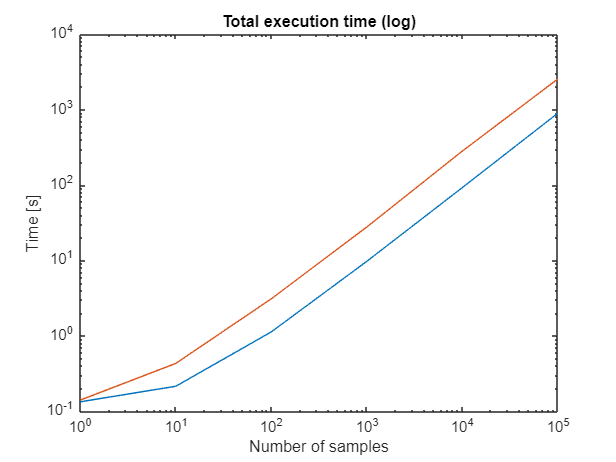

x = [       1,       10,      100,     1000,     10000,     100000];

% Np = 1
y1 = [0.134045, 0.215401, 1.131060, 9.733820, 92.287930, 892.678323];

% Np = 10
y10 = [0.141296, 0.432672, 3.103669, 27.743440, 281.141883, 2537.692314];

figure
loglog(x, y1)
hold on
loglog(x, y10)
hold off
xlabel("Number of samples")
ylabel("Time [s]")
title("Total execution time (log)")

clc
clear all
close all
rng(0)

# M3C Simulation

## Parameters

Simulation and control steps

Tf = 0.2;       % Total simulation time
Ts = 100e-6;    % Shortest sampling time (fastest)
Ns = Tf/Ts      % Number of sampling steps
Ti = 10e-6;	    % Integration step
Ni = Ts/Ti      % Number of integration steps between each ISR (Interrupt Service Routine)
Tsim = linspace(0, Tf, Ni);

% Vxy_max = Ax+Ay;     % Branch voltage

## External system

Input

Ax0 = 7000;
fx0 = 50;
wx0 = 2*pi*fx0;

Output

Ay0 = 5000;
fy0 = 50;
wy0 = 2*pi*fy0;

## Modular Multilevel Matrix Converter

M3C

specsM3C = struct();

% Constants
specsM3C.Constants.Ti  = Ti;       % Integration step
specsM3C.Constants.R   = 1e-3;     % Branch resistance
specsM3C.Constants.L   = 20e-3;    % Branch inductance
specsM3C.Constants.Csm = 5e-3;     % Submodule capacitance
specsM3C.Constants.Nsm = 4;        % Submodules per cluster
specsM3C.Constants.Rx  = 0.1e-3;   % Input filter resistance
specsM3C.Constants.Lx  = 1e-3;     % Input filter inductance
specsM3C.Constants.Ry  = 0.1e-3;   % Output filter resistance
specsM3C.Constants.Ly  = 1e-3;     % Output filter inductance

% Initial Values
specsM3C.InitialValues.is = zeros(9, 1);                    % Cluster current
specsM3C.InitialValues.vc = 1.5 * (Ax0 + Ay0) * ones(9, 1); % Cluster capacitor voltage

M3C = ClassM3C(specsM3C)

## Phase Locked Loop

Input and output PLL

specsPLL = struct();
specsPLL.Ts = Ts;
xi_pll = 1/sqrt(2);
wc_pll = 100*2*pi;
specsPLL.kp = 2*xi_pll*wc_pll
specsPLL.ki = wc_pll^2
specsPLL.u_min = -Inf;
specsPLL.u_max = Inf;

PLLx = ClassPLL(specsPLL)
PLLy = ClassPLL(specsPLL)

[ImperixPLL](https://imperix.com/doc/implementation/synchronous-reference-frame-pll)

## TEB PI and Filter design

% %%% Hand tuned
% kp_pi = 5;
% wn_filt = 2*pi*20;
% ki_pi = 10;

% (Mean cluster capacitor voltage)/(Input current) transfer function
vc_mean_ref = 1.5 * (Ax0 + Ay0);
k_teb = Ax0/(6*vc_mean_ref) / M3C.C
G_teb = k_teb*tf(1, [1, 0])

% %% JOINT PI controller and feedback filter design
% % Pole assignment (three first order)
% % First order pole
% wn_acl = 2*pi*15;        % Natural frequency
% 
% % PI
% kp_pi = wn_acl/k_teb
% ki_pi = wn_acl^2/(3*k_teb)
% % Filter
% wn_filt = 3*wn_acl

%% JOINT PI controller and feedback filter design
% Pole assignment (one second order + one first order)
% Second order pole
xi_acl = 1/sqrt(2);         % Damping factor
wn_acl = 2*pi*20;           % Natural frequency
% First order pole
alpha_acl = 2*pi*20;        % Natural frequency

% PI
kp_pi = wn_acl*(wn_acl+2*xi_acl*alpha_acl)/(k_teb*(2*wn_acl*xi_acl+alpha_acl))
ki_pi = wn_acl^2*alpha_acl/(k_teb*(2*wn_acl*xi_acl+alpha_acl))
% Filter
wn_filt = 2*wn_acl*xi_acl+alpha_acl

## Low Pass Mean Energy Filter

LPF

specsLPF = struct();
specsLPF.Ts = Ts;
specsLPF.wn = wn_filt;
specsLPF.y0 = mean(M3C.vc);

LPF = ClassLPF(specsLPF)

## Total Energy Balance Proportional Integral Controller

PI

ix_max = 200; % Maximum input current

specsPI = struct();
specsPI.Ts = Ts;
specsPI.kp = kp_pi;
specsPI.ki = ki_pi;
specsPI.u_min = -ix_max;
specsPI.u_max = ix_max;

PI = ClassPI(specsPI)

## Cluster Energy Model Predictive Controller

CEMPC

is_max = 250;

specsM3C.Constants.Ti = Ts;

specsCEMPC.M3C = ClassM3C(specsM3C);
specsCEMPC.is_max = is_max;
specsCEMPC.vo_max = (Ax0 + Ay0)/2;
specsCEMPC.Ts = Ts;
specsCEMPC.lambda_z = 2;
specsCEMPC.lambda_o = 0.1;
specsCEMPC.lmax = 10;
specsCEMPC.Np = 1;

CEMPC = ClassCEMPC(specsCEMPC)

## Cluster Current Model Predictive Controller

CCMPC

specsM3C.Constants.Ti = Ts;
specsCCMPC.M3C = ClassM3C(specsM3C);
specsCCMPC.lambda = 0.00005;
CCMPC = ClassCCMPC(specsCCMPC)

## Utils

abc to dq frame of reference

Tabc2dq = @(g) (2/3)*[cos(g), cos(g-2*pi/3), cos(g+2*pi/3); -sin(g), -sin(g-2*pi/3), -sin(g+2*pi/3)];

alpha beta to abc frame of reference and vice versa

Tabc2ab = (2/3)*[1, -1/2, -1/2; 0, sqrt(3)/2, -sqrt(3)/2];
Tab2abc = [1, 0; -1/2, sqrt(3)/2; -1/2, -sqrt(3)/2];
Tab2abc = (1/2)*[2, 0; -1, sqrt(3); -1, -sqrt(3)];

Rotation matrices

% Counter clockwise rotation matrix
rot = @(theta) [cos(theta), -sin(theta);
                sin(theta),  cos(theta)];

% Input
theta = wx0 * Ts;
angles = (0:specsCEMPC.Np-1) * theta;
cos_vals = cos(angles);
sin_vals = sin(angles);
ROTx = reshape([cos_vals; -sin_vals; sin_vals; cos_vals], 2, 2*specsCEMPC.Np)';

% Output
theta = wy0 * Ts;
angles = (0:specsCEMPC.Np-1) * theta;
cos_vals = cos(angles);
sin_vals = sin(angles);
ROTy = reshape([cos_vals; -sin_vals; sin_vals; cos_vals], 2, 2*specsCEMPC.Np)';

% DISCLAIMER: This rotation matrices produce a vector of Np steps starting
% from now, so it actually only predicts Np-1 steps. This has to be taken in
% account in case of control delay compensation.

# Simulation

Buffer

% Initialize
buffer                      = struct();

% Constants
buffer.Ts                   = Ts;                           % Control sample time

% Variables
buffer.is                   = zeros(M3C.m, Ns);             % Cluster current
buffer.ixy                  = zeros(size(M3C.A, 1), Ns);    % External current
buffer.iB                   = zeros(M3C.m, Ns);             % Basic current
buffer.iz                   = zeros(M3C.m, Ns);             % Circulating current
buffer.ie                   = zeros(M3C.n, Ns);             % L.I. circulating current
buffer.vs                   = zeros(M3C.m, Ns);             % Cluster voltage
buffer.vxy                  = zeros(size(M3C.A, 1), Ns);    % External voltage
buffer.vB                   = zeros(M3C.m, Ns);             % Basic voltage
buffer.vo                   = zeros(1, Ns);                 % Common mode voltage
buffer.Ec                   = zeros(M3C.m, Ns);             % Cluster capacitor energy (one-step lookahead)
buffer.vc                   = zeros(M3C.m, Ns);             % Cluster capacitor voltage
buffer.Ec_mean              = zeros(1, Ns);                 % Predicted mean cluster capacitor energy
buffer.Ec_mean_filt         = zeros(1, Ns);                 % Predicted filtered mean cluster capacitor energy
buffer.vc_mean              = zeros(1, Ns);                 % Predicted mean cluster capacitor energy
buffer.vc_mean_filt         = zeros(1, Ns);                 % Predicted filtered mean cluster capacitor voltage

buffer.u_TEB                = zeros(1, Ns);                 % TEB PI control action

buffer.gx                   = zeros(1, Ns);                 % Input voltage angle
buffer.wx                   = zeros(1, Ns);                 % Input voltage frequency
buffer.gy                   = zeros(1, Ns);                 % Output voltage angle
buffer.wy                   = zeros(1, Ns);                 % Output voltage frequency

buffer.gx_pll               = zeros(1, Ns);                 % PLL estimation of input voltage angle
buffer.wx_pll               = zeros(1, Ns);                 % PLL estimation of input voltage frequency
buffer.gy_pll               = zeros(1, Ns);                 % PLL estimation of output voltage angle
buffer.wy_pll               = zeros(1, Ns);                 % PLL estimation of output voltage frequency

buffer.ex_pll               = zeros(1, Ns);                 % Input PLL error
buffer.ux_pll               = zeros(1, Ns);                 % Input PLL control action
buffer.ey_pll               = zeros(1, Ns);                 % Output PLL error
buffer.uy_pll               = zeros(1, Ns);                 % Output PLL control action

buffer.is_ref               = zeros(M3C.m, Ns);
buffer.ixy_ref              = zeros(size(M3C.A, 1), Ns);
buffer.iB_ref               = zeros(M3C.m, Ns);
buffer.iz_ref               = zeros(M3C.m, Ns);
buffer.ie_ref               = zeros(M3C.n, Ns);

Initialize

Ax = Ax0;
Ay = Ay0;
wx = wx0;
wy = wy0;
gx = 0;
gy = 0;

vxa = Ax * cos(gx);
vxb = Ax * cos(gx-2*pi/3);
vxc = Ax * cos(gx+2*pi/3);
vyr = Ay * cos(gy);
vys = Ay * cos(gy-2*pi/3);
vyt = Ay * cos(gy+2*pi/3);
vxy = [vxa; vxb; vxc; vyr; vys; vyt];

vc_mean_ref = 1.5 * (Ax + Ay);
Ec_mean_ref = M3C.C/2 * vc_mean_ref^2;

vc_ref = vc_mean_ref * ones(9, 1);
Ec_ref = Ec_mean_ref * ones(9, 1);

iyd_ref = -100;

Run

% Initialize progress bar
h = waitbar(0, 'Simulating...');

for ts = 1:Ns

%% Maneouver
if ts > Ns/2
    iyd_ref = -100;
end

%% Measure external voltages
vB = M3C.A' * vxy;

%% Input PLL
vxdq = Tabc2dq(PLLx.g) * vxy(1:3);
PLLx = PLLx.estimate(vxdq/norm(vxdq), wx0);

%% Output PLL
vydq = Tabc2dq(PLLy.g) * vxy(4:6);
PLLy = PLLy.estimate(vydq/norm(vydq), wy0);

%% "Measure" converter cluster mean voltage
Ec = M3C.Ec;
vc = M3C.vc;

Ec_mean = mean(Ec);
vc_mean = mean(vc);

%% Low pass filter for mean cluster energy
LPF = LPF.filter(vc_mean);
vc_mean_filt = LPF.yf_t;
Ec_mean_filt = M3C.C / 2 * vc_mean_filt^2;

%% Calculate input currents references (TEB PI)
% dq
PI = PI.control(vc_mean_ref, vc_mean_filt);
ixd_ref = PI.u_t;
ixq_ref = 0;
% abc
ixa_ref = ixd_ref * cos(PLLx.g)          - ixq_ref * sin(PLLx.g);
ixb_ref = ixd_ref * cos(PLLx.g - 2*pi/3) - ixq_ref * sin(PLLx.g - 2*pi/3);
ixc_ref = ixd_ref * cos(PLLx.g + 2*pi/3) - ixq_ref * sin(PLLx.g + 2*pi/3);

%% Calculate output currents references (Converter application)
% dq
% iyd_ref = 100;
iyq_ref = 0;
% abc
iyr_ref = iyd_ref * cos(PLLy.g)          - iyq_ref * sin(PLLy.g);
iys_ref = iyd_ref * cos(PLLy.g - 2*pi/3) - iyq_ref * sin(PLLy.g - 2*pi/3);
iyt_ref = iyd_ref * cos(PLLy.g + 2*pi/3) - iyq_ref * sin(PLLy.g + 2*pi/3);

%% Concatenate external currents references
ixy_ref = [ixa_ref; ixb_ref; ixc_ref; iyr_ref; iys_ref; iyt_ref];

%% Basic currents references
iB_ref = M3C.pinvA * ixy_ref;

%% Predict external voltages/currents
vB_pred = predict_basic_assuming_symmetrical(vxy, specsCEMPC.Np, ROTx, ROTy, Tabc2ab, Tab2abc, M3C.pinvA);
iB_pred = predict_basic_assuming_symmetrical(M3C.ixy, specsCEMPC.Np, ROTx, ROTy, Tabc2ab, Tab2abc, M3C.pinvA);

%% Cluster energy MPC
CEMPC = CEMPC.control(Ec, vB_pred, iB_pred);

%% Cluster current MPC
is_ref = CEMPC.iz_ref + iB_ref;
CCMPC = CCMPC.control(is_ref, vc_mean_ref, M3C.is, vB, CEMPC.vo_ref);

%% Store variables
buffer.is(:, ts) = M3C.is;
buffer.ixy(:, ts) = M3C.ixy;
buffer.iB(:, ts) = M3C.iB;
buffer.iz(:, ts) = M3C.iz;
buffer.ie(:, ts) = M3C.ie;
buffer.vs(:, ts) = CCMPC.vs;
buffer.vxy(:, ts) = vxy;
buffer.vB(:, ts) = vB;
buffer.vo(:, ts) = CEMPC.vo_ref;
buffer.Ec(:, ts) = Ec;
buffer.vc(:, ts) = vc;
buffer.Ec_mean(ts) = Ec_mean;
buffer.Ec_mean_filt(ts) = Ec_mean_filt;
buffer.vc_mean(ts) = vc_mean;
buffer.vc_mean_filt(ts) = vc_mean_filt;

buffer.u_TEB(ts) = PI.u_t;

buffer.gx(ts) = gx;
buffer.wx(ts) = wx;
buffer.gy(ts) = gy;
buffer.wy(ts) = wy;

buffer.gx_pll(ts) = PLLx.g;
buffer.wx_pll(ts) = PLLx.w;
buffer.gy_pll(ts) = PLLy.g;
buffer.wy_pll(ts) = PLLy.w;

buffer.ex_pll(ts) = PLLx.e_t;
buffer.ux_pll(ts) = PLLx.u_t;
buffer.ey_pll(ts) = PLLy.e_t;
buffer.uy_pll(ts) = PLLy.u_t;

buffer.is_ref(:, ts) = is_ref;
buffer.ixy_ref(:, ts) = ixy_ref;
buffer.iB_ref(:, ts) = iB_ref;
buffer.iz_ref(:, ts) = CEMPC.iz_ref;
buffer.ie_ref(:, ts) = CEMPC.ie_ref;

%% Integrate external system and converter
for ti = 1:Ni
    % Update model
    M3C = M3C.step(CCMPC.vs, vxy, CEMPC.vo_ref);
    
    % Update external system
    gx = mod(gx + wx * Ti, 2*pi);
    gy = mod(gy + wy * Ti, 2*pi);
    vxa = Ax * cos(gx);
    vxb = Ax * cos(gx-2*pi/3);
    vxc = Ax * cos(gx+2*pi/3);
    vyr = Ay * cos(gy);
    vys = Ay * cos(gy-2*pi/3);
    vyt = Ay * cos(gy+2*pi/3);
    vxy = [vxa; vxb; vxc; vyr; vys; vyt];
end

% Update progress bar
waitbar(ts/Ns, h, sprintf('Progreso: %d%%', round((ts/Ns)*100)));

end

% Close progress bar
close(h)

# Plot

run("Plot.mlx")